Vamos a usar MATLAB para hacer la convolución Richardson-Lucy y ver cuanto tiempo tarda.

%% Deconvolución Lucy-Richardson Matlab %%
%Hay que instalarse Image Processing Toolbox

% Cargar la imagen de prueba
img = single(imread('ImagenPrueba.jpg'));
%Cargamos la imagen borrosa y con ruido
img_n= single(imread("blurrednoisy_img.jpg"));
%Cargamos la PSF
psf= single(imread("psf.jpg"));

% Normalizar la PSF
psf = psf / sum(psf(:));

% Deconvolucionar 2D con opciones predeterminadas

res = deconvlucy(img_n, psf, 30);
code_to_measure = @() deconvlucy(img_n, psf, 30);

% Medir el tiempo de ejecución
execution_time = timeit(code_to_measure);
disp(['Tiempo de ejecución: ', num2str(execution_time), ' segundos']);

Tiempo de ejecución: 0.14626 segundos


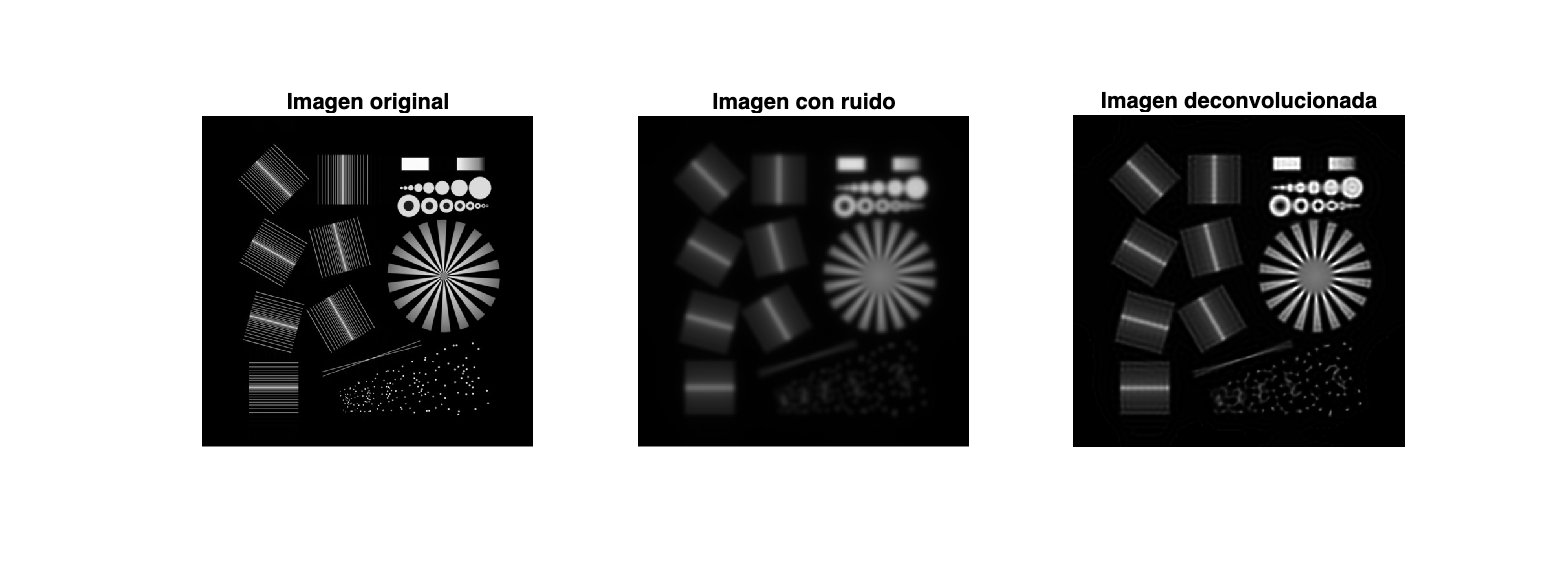


% Mostrar los resultados finales junto con la versión original y borrosa
figure('Position', [100, 100, 1600, 600]);  % [left, bottom, width, height]
subplot(1, 3, 1); imshow(uint8(img)); title('Imagen original');
subplot(1, 3, 2); imshow(uint8(img_n)); title('Imagen con ruido');
subplot(1, 3, 3); imshow(uint8(res)); title('Imagen deconvolucionada');


%Guardamos la figura resultante

%save_path = 'Path/donde/guardar/imagen.png';
%saveas(gcf, save_path);